# Numerical Integration:

Most common numerical integration rules are:

## 1.Trapezoidal Rule

## 2.Simpson's 1/3rd Rule

## 3.Simpson's 3/8th Rule

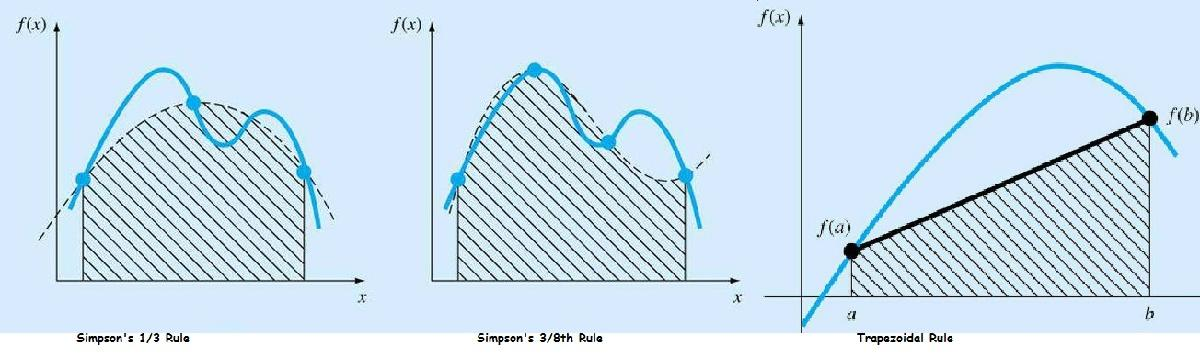.

For single application

Trapezoidal Rule: $\int_a^b f\left(x\right)dx=\frac{h}{2}\left\lbrack f\left(a\right)+f\left(a+h\right)\right\rbrack$, where $h=b−a$

Simpson's 1/3rd Rule: $\int_a^b f\left(x\right)\text{dx}=\frac{h}{3}\left\lbrack f\left(a\right)+4f\left(a+h\right)+f\left(a+2h\right)\right\rbrack$, where $h=\frac{b−a}{2}$

Simpson's 3/8th Rule: $\int_a^b f\left(x\right)\text{dx}=\frac{3h}{8}\left\lbrack f\left(a\right)+3f\left(a+h\right)+3f\left(a+2h\right)+f\left(a+3h\right)\right\rbrack$, where $h=\frac{b−a}{3}$

## For multiple segments direct formula:

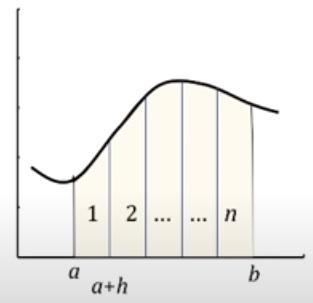

 Trapezoidal Rule: If we write, $f\left(a\right)=f_0 ;f\left(a+h\right)=f_1 ;\ldotp \ldotp \ldotp \ldotp \ldotp f\left(a+nh\right)=f_n$; where a+nh=b

Then, $\int_a^b f\left(x\right)dx=\frac{h}{2}\left\lbrack f_0 +2\left(f_1 +f_2 +\ldotp \ldotp \ldotp \ldotp +f_{n−1} \right)+f_n \right\rbrack$

Simpson's 1/3 Rule: If we write, $f\left(a\right)=f_0 ;f\left(a+h\right)=f_1 ;\ldotp \ldotp \ldotp \ldotp \ldotp f\left(a+\text{nh}\right)=f_n$; where a+nh=b & n=even number

Then, $\int_a^b f\left(x\right)\text{dx}=\frac{h}{3}\left\lbrack f_0 +4\left(f_1 +f_3 +\ldotp \ldotp \ldotp \ldotp +f_{n−1} \right)+2\left(f_2 +f_4 +\ldotp \ldotp \ldotp \ldotp +f_{n−2} \right)+f_n \right\rbrack$

Simpson's 3/8 Rule: If we write, $f\left(a\right)=f_0 ;f\left(a+h\right)=f_1 ;\ldotp \ldotp \ldotp \ldotp \ldotp f\left(a+\text{nh}\right)=f_n$; where a+nh=b & n is multiple of 3

Then, $\int_a^b f\left(x\right)\text{dx}=\frac{3h}{8}\left\lbrack f_0 +3\left(f_1 +f_2 +f_4 +f_5 +\ldotp \ldotp \ldotp \ldotp +f_{n−2} +f_{n−1} \right)+2\left(f_3 +f_6 +\ldotp \ldotp \ldotp \ldotp +f_n \right)\right\rbrack$

## Example:

Find the Numerical integration of $f\left(x\right)=2−x+lnx$;In the limit a=1 & b=2. consider intervals n={5,10,15,20} & make a log log plot of error

Using: Trapezoidal Rule & Simpson's 1/3 Rule

Solution:

First create a function file to evalute the given function

Give name of the function file as $myFunc$.m

## edit myFunc.m

function f=myFunc(x)

f=2-x+log(x);

end

Now calculate the true value of the integration 


$$\int_a^b \left\lbrack 2−x+log\left(x\right)\right\rbrack dx={\left\lbrack x−\frac{x^2 }{2}+xlnx\right\rbrack }_a^b$$


a=1;
b=2;
trueVal=(b-b^2/2+b*log(b))-(a-a^2/2+a*log(a))

trueVal = 0.8863

## Trapezoidal rule:


n=20;% You can change the values of n and check the error or you can assign n as an array and store error as a vector.
h=(b-a)/n

h = 0.0500

x=a:h:b

x =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


f=myFunc(x)

f =     1.0000    0.9988    0.9953    0.9898    0.9823    0.9731    0.9624    0.9501    0.9365    0.9216    0.9055    0.8883    0.8700    0.8508    0.8306    0.8096    0.7878    0.7652    0.7419    0.7178    0.6931


## Method 1-Trapezoidal: Using single application formula at each segment and then sum all the integrals

numValue_trap_intrvl=zeros(1,n);
for i=1:n
    numValue_trap_intrvl(i)=(h/2)*(f(i)+f(i+1));
end
numValue_trap=sum(numValue_trap_intrvl)

numValue_trap = 0.8862

## Method 2-Trapezoidal: Using direct formula $\int_a^b f\left(x\right)\text{dx}=\frac{h}{2}\left\lbrack f_0 +2\left(f_1 +f_2 +\ldotp \ldotp \ldotp \ldotp +f_{n−1} \right)+f_n \right\rbrack$

numValue_trap_direct=(h/2)*(f(1)+2*sum(f(2:n))+f(n+1))

numValue_trap_direct = 0.8862

## Error in Trapezoidal Rule

err_trap=abs(trueVal-numValue_trap)

err_trap = 1.0415e-04

## Simpson's 1/3 Rule:


n=20;% Make sure n is even
h=(b-a)/n

h = 0.0500

x=a:h:b

x =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


f=myFunc(x)

f =     1.0000    0.9988    0.9953    0.9898    0.9823    0.9731    0.9624    0.9501    0.9365    0.9216    0.9055    0.8883    0.8700    0.8508    0.8306    0.8096    0.7878    0.7652    0.7419    0.7178    0.6931


## Method 1-Simpson's 1/3 Rule: Using single application formula at each segment and then sum all the integrals

numValue_simp1_3_intrvl=zeros(1,n);
for i=1:2:n-1
    numValue_simp1_3_intrvl(i)=(h/3)*(f(i)+4*f(i+1)+f(i+2));
end
numValue_simp1_3=sum(numValue_simp1_3_intrvl)

numValue_simp1_3 = 0.8863

## Method 2-Simpson's 1/3 Rule: Using direct formula $\int_a^b f\left(x\right)\text{dx}=\frac{h}{3}\left\lbrack f_0 +4\left(f_1 +f_3 +\ldotp \ldotp \ldotp \ldotp +f_{n−1} \right)+2\left(f_2 +f_4 +\ldotp \ldotp \ldotp \ldotp +f_{n−2} \right)+f_n \right\rbrack$

numValue_simp1_3_direct=(h/3)*(f(1)+4*sum(f(2:2:n))+2*sum(f(3:2:n-1))+f(n+1))

numValue_simp1_3_direct = 0.8863

## Error in Simpson's 1/3 Rule

err_trap=abs(trueVal-numValue_simp1_3)

err_trap = 6.0526e-08

## Inbuilt MATLAB function integral 

Steps:

Create a function file

then use $integral(@(x) functionFileName(x),a,b)$ to calculate integral in the range a to b

## Example:

It is known that when hot oil is flowing over a flat plate, wall shear stress is varying along the length of the plate $\tau_w \left(x\right)=0\ldotp 332{u_{\infty } \sqrt{\rho \mu u_{\infty } }x}^{−\frac{1}{2}}$, where $\rho =900\frac{kg}{m^3 },\text{ }u_{\infty } =1\frac{m}{s},\text{ }\mu =0\ldotp 06Pa\ldotp s$, Length of the plate is l=2m. Find the total drag force acting on the plate.

## Solution:

Create the function file with name $wallShear.m$

Use integral function to calculate Drag=$\int_0^l \tau_w \left(x\right)dx$


l=2; %length of the plate in m
D=integral(@(y) wallShear(y),0,l)

D = 6.9005

## Assignment: 

- $\int_a^b \left\lbrack 2−x+log\left(x\right)\right\rbrack dx={\left\lbrack x−\frac{x^2 }{2}+xlnx\right\rbrack }_a^b$  Use Simpson's 3/8 rule to solve the the problem & find the error take n=20, a=1,b=2

- It is known that when hot oil is flowing over a flat plate, wall shear stress is varying along the length of the plate $\tau_w \left(x\right)=0\ldotp 332{u_{\infty } \sqrt{\rho \mu u_{\infty } }x}^{−\frac{1}{2}}$, where $\rho =900\frac{kg}{m^3 },\text{ }u_{\infty } =1\frac{m}{s},\text{ }\mu =0\ldotp 06Pa\ldotp s$, Length of the plate is l=2m. Find the total drag force acting on the plate. Use numerical integration method to solve this problem.

## Solution 2:

l=2;
n=100;% Make sure n is even for Simpson's 1/3 rule
a=.001;
b=l;
h=(b-a)/n

h = 0.0200

x=a:h:b

x =     0.0010    0.0210    0.0410    0.0610    0.0810    0.1010    0.1209    0.1409    0.1609    0.1809    0.2009    0.2209    0.2409    0.2609    0.2809    0.3009    0.3208    0.3408    0.3608    0.3808    0.4008    0.4208    0.4408    0.4608    0.4808    0.5008    0.5207    0.5407    0.5607    0.5807    0.6007    0.6207    0.6407    0.6607    0.6807    0.7007    0.7206    0.7406    0.7606    0.7806    0.8006    0.8206    0.8406    0.8606    0.8806    0.9006    0.9205    0.9405    0.9605    0.9805


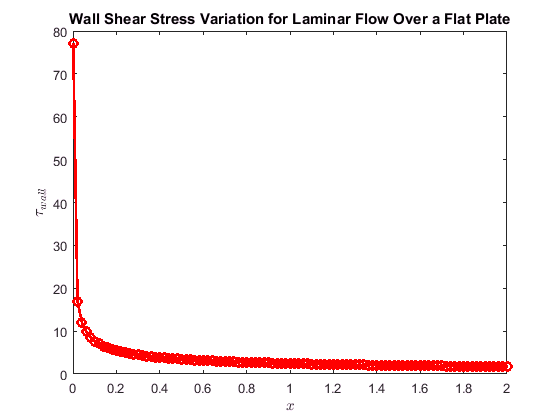

% Wall Shear Stress
tau=wallShear(x);
plot(x,tau,'r-o','LineWidth',2)
xlabel('$x$','Interpreter','latex');
ylabel('$\tau_{wall}$','FontSize',12,'Interpreter','latex');
title('Wall Shear Stress Variation for Laminar Flow Over a Flat Plate');

% To find drag per unit width on the plate we have integrate tau along x 

% Using Simpson's 1/3 rule
numValue_simp1_3_intrvl=zeros(1,n);
for i=1:2:n-1
    numValue_simp1_3_intrvl(i)=(h/3)*(tau(i)+4*tau(i+1)+tau(i+2));
end
numValue_simp1_3=sum(numValue_simp1_3_intrvl)

numValue_simp1_3 = 6.9562

%Using Trapizoidal Rule
numValue_trap_intrvl=zeros(1,n);
for i=1:n
    numValue_trap_intrvl(i)=(h/2)*(tau(i)+tau(i+1));
end
numValue_trap=sum(numValue_trap_intrvl)

numValue_trap = 7.1457